# Bicopter Simulink/Simscape Model For System Identification and Controller Design

## Eniko T Enikov, Melda Ulusoy, and Jon Loftin, $\copyright$2024

This tutorial is designed to supplement the Bi-Copter phyiscal experiment with a simulation tool. This module presents

- System identificaiton experiment

- Controller design using state space approach 

- Integraral (servo) controller design using state space approach.

## System Identification Experiment (Open Loop Response)

Start the model using Mode=3, which subjects the system to a test input. Before running the simulation, you must generate a test input. This is done automatically in the Simulink/Simscape model Pre-Load callback. However in this tutorial these commands are listed explicitly.

t=[0:0.1:50];
test=[[0:0.1:50]' idinput(501,'rbs',[0 0.24])*1.5];
ref=[t' 0.5*(t<20)'-0.5*(t>=20)'];


In order to compile and run the model, all referenced variables must be pre-defined. This includes the desired Mode , and the two controllers C and Ci, hence

Mode=3;
C=ss(1);
Ci=ss(1); % Dummy controllers

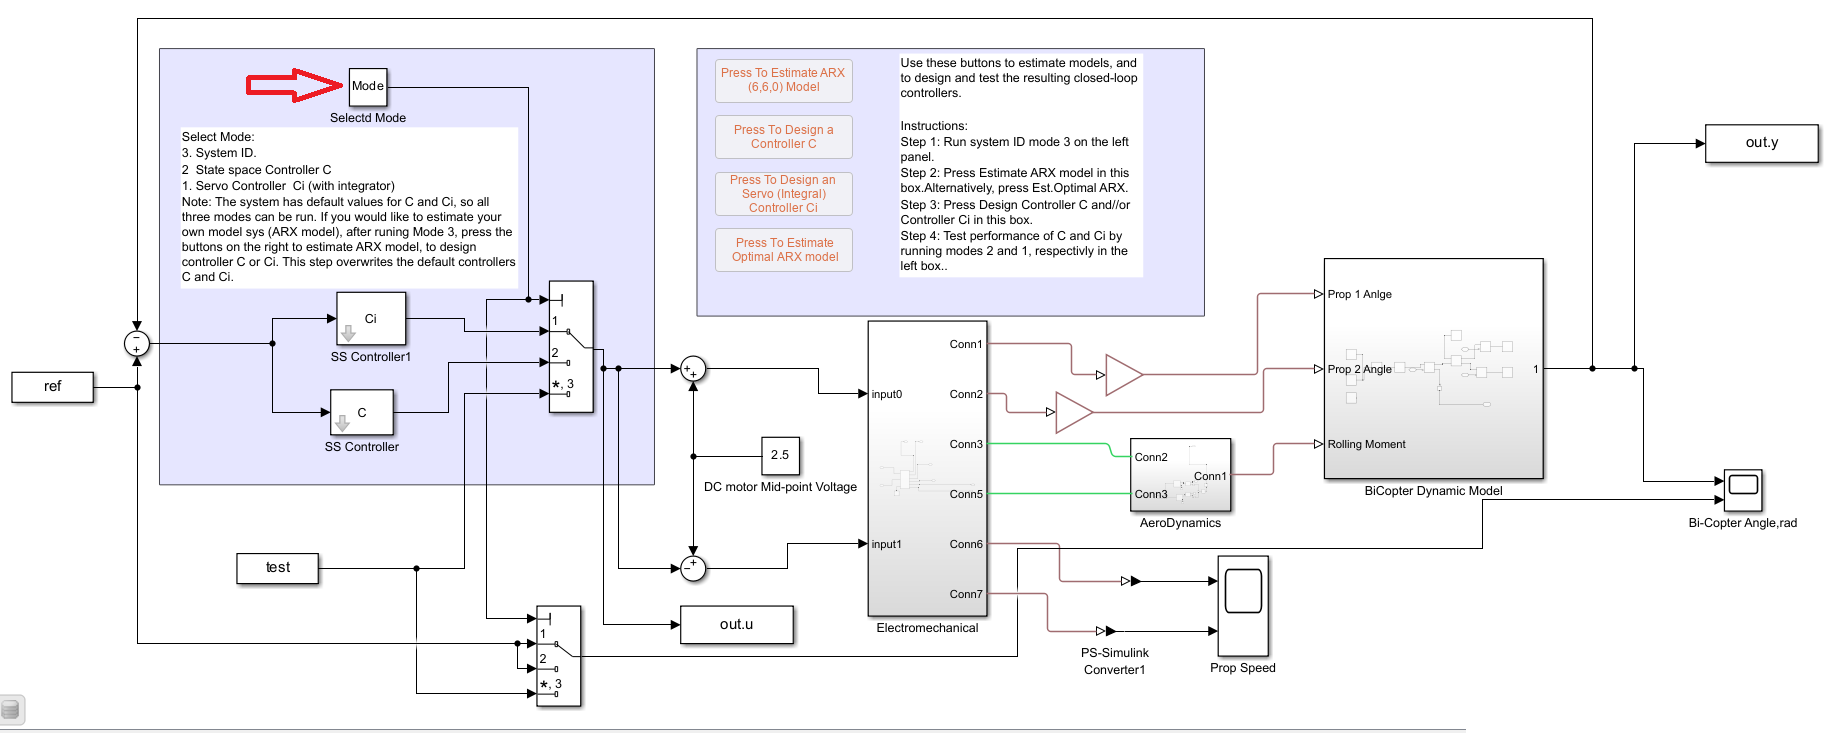

bicopterassm_final_DataFile
out=sim("bicopterassm_final.slx");

CC =   -21.0457  -44.8962   36.2588    0.3993   -0.0970    0.0918


After the simulation has finished, one can examine the response by plotting the test input sequence and the resulting output. 

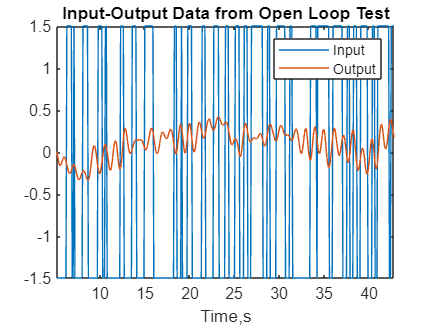

figure;
plot(test(:,1),test(:,2),test(:,1),out.y.data); axis([0 50 -1 1]);
legend('Input','Output');xlabel('Time,s')
title('Input-Output Data from Open Loop Test')

xlim([5.2 42.8])
ylim([-1.5 1.5])

drawnow

To identify an ARX model, use system identification toolbox commands

dat=iddata(out.y.data(250:end),out.u.data(250:end),0.1);
sys=arx(dat,[6 6 0])

sys =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                  
  A(z) = 1 - 2.078 z^-1 + 1.502 z^-2 - 0.2866 z^-3 - 0.06185 z^-4 + 0.07798 z^-5 - 0.1371 z^-6       
                                                                                                     
  B(z) = -0.0001768 + 0.002054 z^-1 + 0.003166 z^-2 + 0.001825 z^-3 + 0.0009049 z^-4 - 0.0002519 z^-5
                                                                                                     
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=0
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "dat".   
Fit to estimation data: 96.08% (prediction focus)
FPE: 3.076e-05, MSE: 2.666e-05                   
 


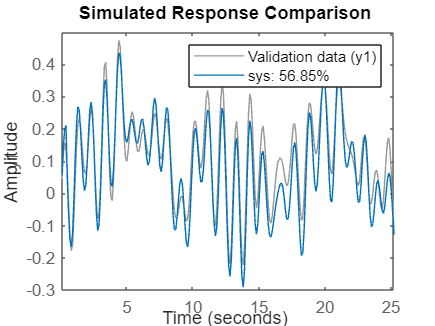

compare(dat,sys);shg

## State Space Controller Design

With the model "sys" identified in the previous step, we design a discrete-time full-state observer/controller. For details on the formulas refer to texbooks such as Ogata's Modern Control Engineering and  Discrete Time Control Systems. In the following with use LQR design to select closed-loop poles of the system. The observer poles are placed on top of the closed loop poles, i.e. each pole appears twice in the overall closed-loop system. The design procedure can be executed by pressing the corresponding button 

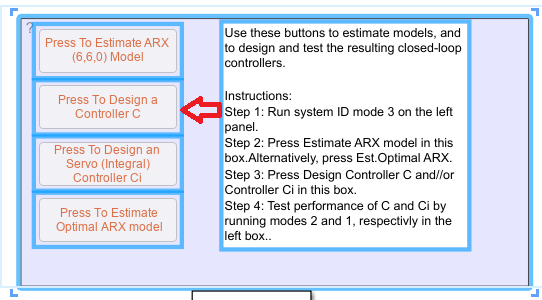

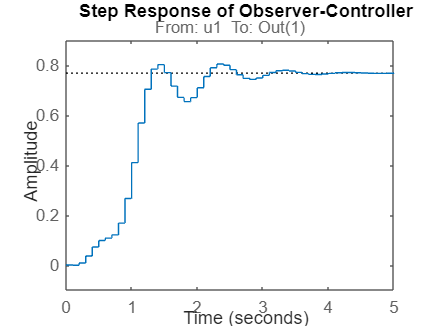

figure
syss=ss(sys);
[K,S,CLP] = dlqr(syss.A,syss.B,syss.C'*syss.C,.0008,0);
Ke =acker(syss.A',syss.C',CLP)';
Aoc=syss.A-syss.B*K-Ke*syss.C;Boc=Ke;Coc=K;
C=ss(Aoc,Boc,Coc,0,0.1);shg
step(feedback(C*syss,1));title('Step Response of Observer-Controller');shg

## Sevo Controller Design

To design a servo (integral) controller, we add an integrator Gi to the model increasing its order  by one. The design procedure is the same and can be excuted by pressing the corresponding button

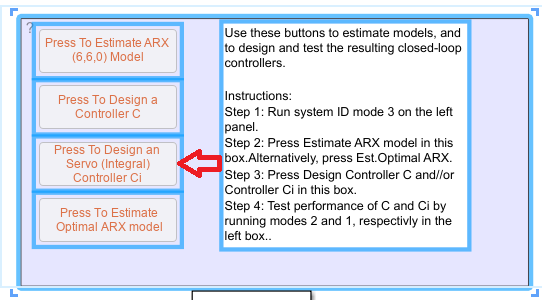

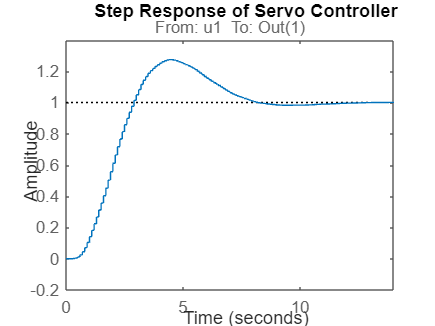

syss=ss(sys);
[K,S,CLP] = dlqr(syss.A,syss.B,syss.C'*syss.C,.0008,0);
Ke =acker(syss.A',syss.C',CLP)';
Aoc=syss.A-syss.B*K-Ke*syss.C;Boc=Ke;Coc=K;
% Integrator added to the ss model
Gi=tf([1 0],[1 -1],.1);
sysi=sys*Gi;
% closed loop poles
[K,S,CLP] = dlqr(sysi.A,sysi.B,sysi.C'*sysi.C,2,0);
Ke =acker(sysi.A',sysi.C',CLP)';
Aoc=sysi.A-sysi.B*K-Ke*sysi.C;Boc=Ke;Coc=K;
Ci=ss(Aoc,Boc,Coc,0,0.1)*Gi; % Integrator is moved to the controller
step(feedback(Ci*sys,1));title('Step Response of Servo Controller');shg

## Testing Of The Observer-Controller

To test the Observer-Controller, use Mode=2.

Mode=2

Mode = 2

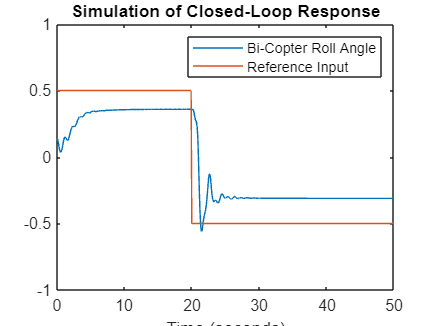

out=sim('bicopterassm_final.slx');
plot(out.tout, out.y.data,out.tout,ref(:,2))
ylim([-1 1])
legend('Bi-Copter Roll Angle','Reference Input')
xlabel('Time (seconds)');title('Simulation of Closed-Loop Response')

## Testing of the Servo Controller

To test the servo controller, use Mode=1 and press the play button

Mode=1 

Mode = 1

out=sim('bicopterassm_final.slx');
plot(out.tout, out.y.data,out.tout,ref(:,2))
ylim([-1 1])
title('Simulaitno of the Closed-Loop Response of Servo Controller')
legend('Bi-Copter Roll Angle','Reference Input')
xlabel('Time (seconds)')